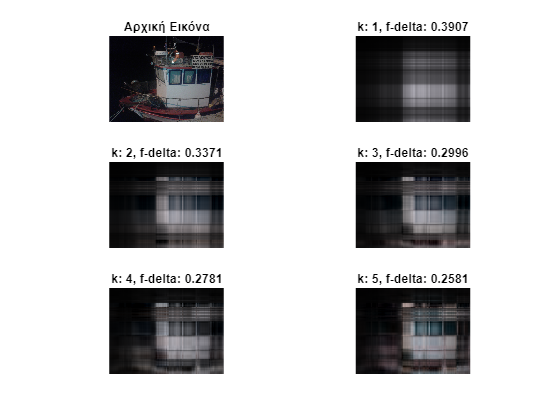

Πίνακας κόστους αποθήκευσης: p5boat.jpg


k       f-delta        Kruskal (bytes)    Πολυδιάστατο array (bytes)   Αναπαράσταση ως πλήρη τανυστή (bytes)


1       0.3907         35864               117964800           117965160           
2       0.3371         71728               117964800           117965160           
3       0.2996         107592              117964800           117965160           
4       0.2781         143456              117964800           117965160           
5       0.2581         179320              117964800           117965160           
6       0.2471         215184              117964800           117965160           
7       0.2352         251048              117964800           117965160           
8       0.2258         286912              117964800           117965160           
9       0.2186         322776              117964800           117965160           
10      0.2107         358640              117964800           117965160           


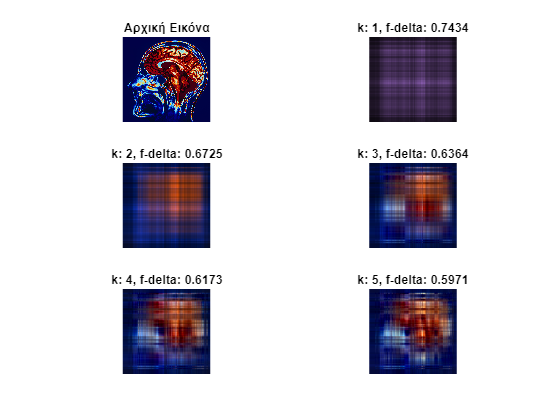

Πίνακας κόστους αποθήκευσης: egkefalos.jpg


k       f-delta        Kruskal (bytes)    Πολυδιάστατο array (bytes)   Αναπαράσταση ως πλήρη τανυστή (bytes)


1       0.7434         14216               18878400            18878760            
2       0.6725         28432               18878400            18878760            
3       0.6364         42648               18878400            18878760            
4       0.6173         56864               18878400            18878760            
5       0.5971         71080               18878400            18878760            
6       0.5818         85296               18878400            18878760            
7       0.5764         99512               18878400            18878760            
8       0.5588         113728              18878400            18878760            
9       0.5479         127944              18878400            18878760            
10      0.5379         142160              18878400            18878760            


clear all;
rng(236182); 
images = {'p5boat.jpg', 'egkefalos.jpg'}; % Λίστα εικόνων
f_delta_thresholds = [0.5, 0.7, 0.9]; 
max_rank = 10;
plot_ranks = [1, 2, 3, 4, 5]; 
% Φόρτωση εικόνας
for img_index = 1:length(images)
    img = imread(images{img_index}); 
    img = double(img); 
    tensor_data = tensor(img); % Δημιουργεία Τανυστή 

    % Κόστος αποθήκευση πλήρη πίνακα  = Μέγεθος εικόνας Χ 8 bytes
    full_array_cost = numel(img) * 8; 
    results = struct();

    
    figure('Name', ['Approximations for ', images{img_index}], 'NumberTitle', 'off');
    subplot(3, 2, 1);
    imshow(uint8(img), []); % Εμφάνιση αρχικής εικόνας
    title('Αρχική Εικόνα');

    plot_index = 2; 
    % διάσπαση CP χρησιμοποιώντας ALS
    for k = 1:max_rank
        try
            model = cp_als(tensor_data, k, 'printitn', 0); % CP Διάσπαση
            approx_tensor = full(model); % Πλήρης προσέγγιση
            f_delta = norm(tensor_data - approx_tensor) / norm(tensor_data); % Υπολογισμός f-delta 

            % Κόστος αποθήκευσης σε αναπραάρασταση Kruskal 
            kruskal_elements = 0;
            for dim = 1:ndims(tensor_data)
                kruskal_elements = kruskal_elements + numel(model.U{dim});
            end
            kruskal_cost = kruskal_elements * 8; % Κόστος σε bytes
            tensor_info = whos('tensor_data'); 
            tensor_struct_cost = tensor_info.bytes; % Κόστος αποθήκευσης σε bytes

            
            results(k).rank = k;
            results(k).f_delta = f_delta;
            results(k).kruskal_cost = kruskal_cost;
            results(k).full_array_cost = full_array_cost;
            results(k).tensor_struct_cost = tensor_struct_cost;

            
            if ismember(k, plot_ranks)
                subplot(3, 2, plot_index); % Υπολογισμός subplot
                imshow(uint8(double(approx_tensor)), []); 
                title(sprintf('k: %d, f-delta: %.4f', k, f_delta)); % Τίτλος με rank και f-delta
                plot_index = plot_index + 1; 
            end
        end
    end

    disp(['Πίνακας κόστους αποθήκευσης: ', images{img_index}]);
    disp('k       f-delta        Kruskal (bytes)    Πολυδιάστατο array (bytes)   Αναπαράσταση ως πλήρη τανυστή (bytes)');

    % Πίνακας για την σύγκριση κόστους αποθήκευσης
    for k = 1:max_rank
        if ~isempty(results(k).rank)
            disp(sprintf('%-8d%-15.4f%-20d%-20d%-20d', ...
                results(k).rank, results(k).f_delta, ...
                results(k).kruskal_cost, results(k).full_array_cost, ...
                results(k).tensor_struct_cost));
        end
    end
end

## **Σχολιασμός Αποτελεσμάτων **

Σχετικά με τον κόστος αποθήκευσης παρατηρούμε ότι κατά την αναπαράσταση kruskal έχουμε το μικρότερο  κόστος. Ενώ κατα την αναπαράσταση με πολυδιάστατο πίνακα ή τανυστή έχοουμε το ίδιο κόστος.  Τέλος βλεπουμε ότι όσο αυξάνεται το κ η εικόνα τείνει προς την αρχική.